# OGLO notebook 4d

hnxj@github

### FEF

xG = z{9};

y = squeeze(mean(mean(xG{1}{1}, 1), 2));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgx_fef = zeros([12, size(p1)]);

parfor ik = 1:size(xG, 2)

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2)

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1)

            for lk = 1:size(xG2, 2)

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                y(isinf(y)) = 0;
                y(isnan(y)) = 0;
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgx_fef(ik, :, :) = squeeze(pgx_fef(ik, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

cond : 7
cond : 4
cond : 3
cond : 2
cond : 12
cond : 11
cond : 10
cond : 6
cond : 8
cond : 5
cond : 9
cond : 1


y = squeeze(mean(xG3(:, 21, :), 1));
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.25, "OverlapPercent", 90);

save("lfpData\TFRs09_OGLO_FEF", "pgx_fef", "-v7.3");

load("lfpData\TFRs09_OGLO_FEF.mat", "pgx_fef");

pgx = zeros(size(pgx_fef));

for ik = 1:size(pgx_fef, 2)

    for ij = 1:size(pgx_fef, 1)
    
        pgx(ij, ik, :) = (pgx_fef(ij, ik, :))/mean(pgx_fef(ij, ik, 1:15));

    end

end

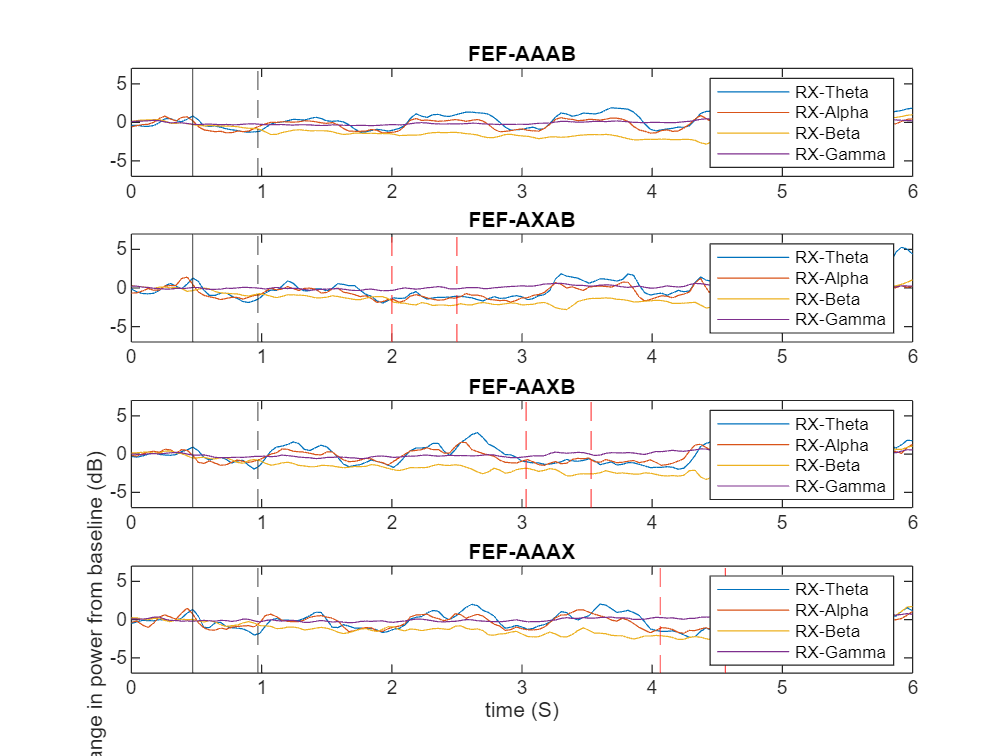

t = linspace(0, 6, 141);
figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(1, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(1, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(1, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(1, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("FEF-AAAB");
ylim([-7 7]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("FEF-AXAB");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(3, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(3, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(3, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(3, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("FEF-AAXB");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(4, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(4, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(4, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(4, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("FEF-AAAX");ylim([-7 7]);
% xlim([0.4 6.0]);

fname = "FEF_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

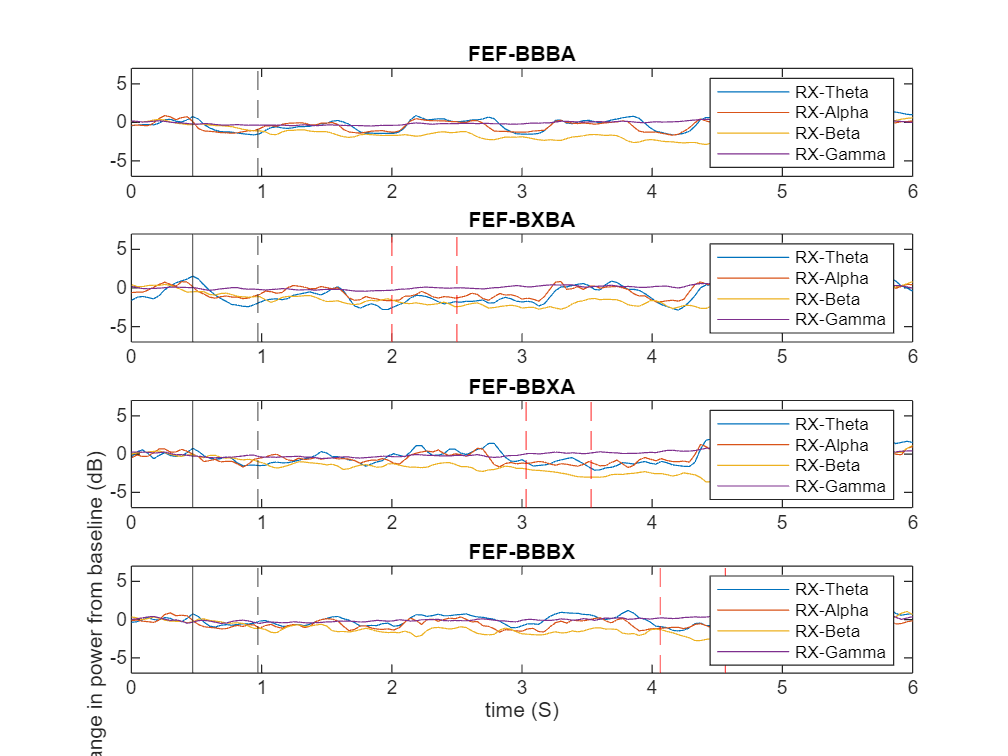

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(5, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(5, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(5, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(5, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("FEF-BBBA");
ylim([-7 7]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(6, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(6, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(6, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(6, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("FEF-BXBA");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(7, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(7, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(7, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(7, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("FEF-BBXA");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(8, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(8, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(8, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(8, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("FEF-BBBX");ylim([-7 7]);
% xlim([0.4 6.0]);

fname = "FEF_TFRBandplot_2";
print(gcf,'-vector','-dsvg',fname +".svg");

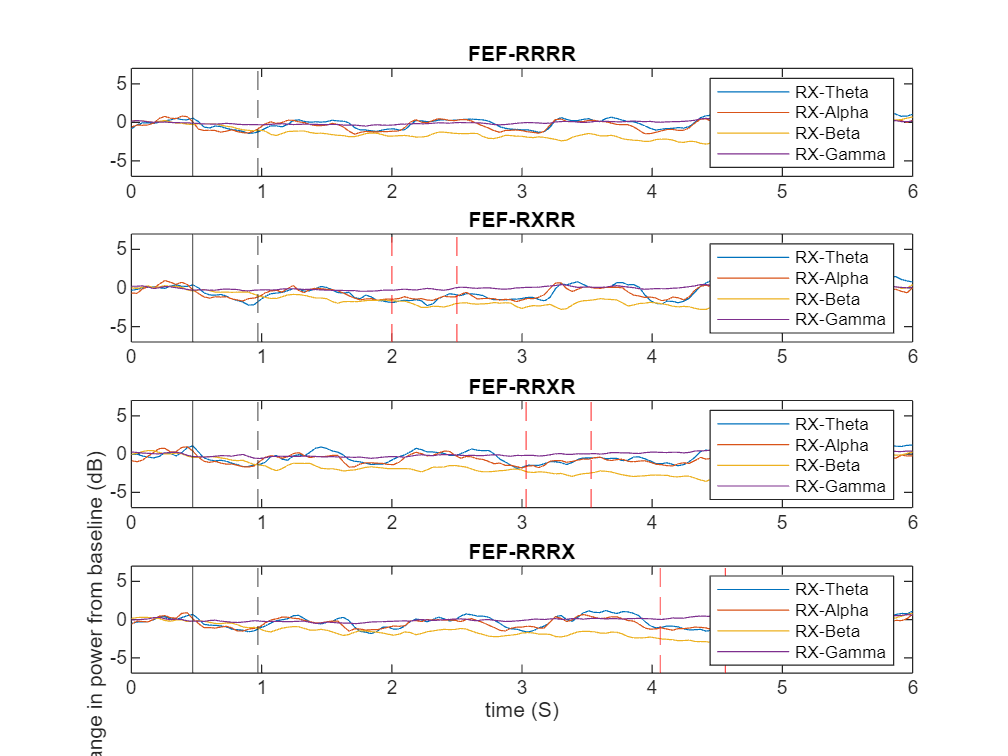

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(9, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(9, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(9, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(9, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("FEF-RRRR");
ylim([-7 7]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(10, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(10, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(10, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(10, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("FEF-RXRR");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(11, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(11, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(11, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(11, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("FEF-RRXR");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(12, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(12, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(12, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(12, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("FEF-RRRX");ylim([-7 7]);
% xlim([0.4 6.0]);

fname = "FEF_TFRBandplot_3";
print(gcf,'-vector','-dsvg',fname +".svg");

### PFC

xG = z{10};

y = squeeze(mean(mean(xG{1}{1}, 1), 2));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgx_pfc = zeros([12, size(p1)]);

parfor ik = 1:size(xG, 2)

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2)

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1)

            for lk = 1:size(xG2, 2)

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                y(isinf(y)) = 0;
                y(isnan(y)) = 0;
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgx_pfc(ik, :, :) = squeeze(pgx_pfc(ik, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

y = squeeze(mean(xG3(:, 21, :), 1));
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.25, "OverlapPercent", 90);

save("lfpData\TFRs10_OGLO_PFC", "pgx_pfc", "-v7.3");

load("lfpData\TFRs10_OGLO_PFC.mat", "pgx_pfc");

pgx = zeros(size(pgx_pfc));

for ik = 1:size(pgx_pfc, 2)

    for ij = 1:size(pgx_pfc, 1)
    
        pgx(ij, ik, :) = (pgx_pfc(ij, ik, :))/mean(pgx_pfc(ij, ik, 1:15));

    end

end

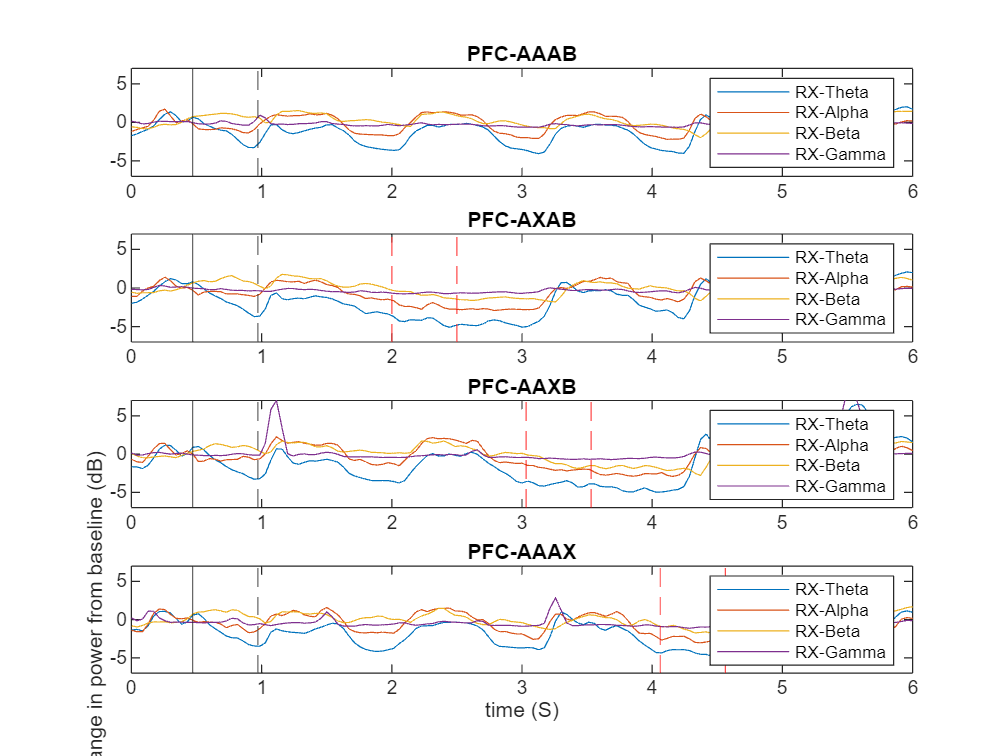

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(1, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(1, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(1, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(1, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("PFC-AAAB");
ylim([-7 7]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("PFC-AXAB");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(3, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(3, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(3, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(3, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("PFC-AAXB");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(4, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(4, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(4, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(4, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("PFC-AAAX");ylim([-7 7]);
% xlim([0.4 6.0]);

fname = "PFC_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

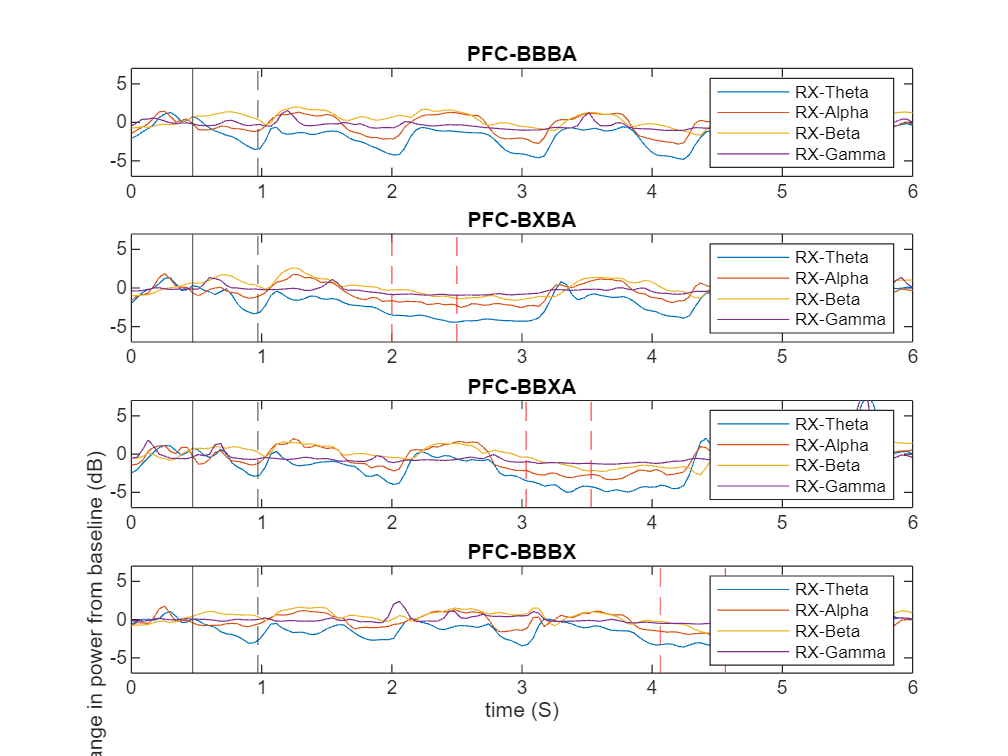

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(5, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(5, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(5, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(5, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("PFC-BBBA");
ylim([-7 7]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(6, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(6, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(6, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(6, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("PFC-BXBA");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(7, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(7, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(7, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(7, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("PFC-BBXA");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(8, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(8, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(8, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(8, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("PFC-BBBX");ylim([-7 7]);
% xlim([0.4 6.0]);

fname = "PFC_TFRBandplot_2";
print(gcf,'-vector','-dsvg',fname +".svg");

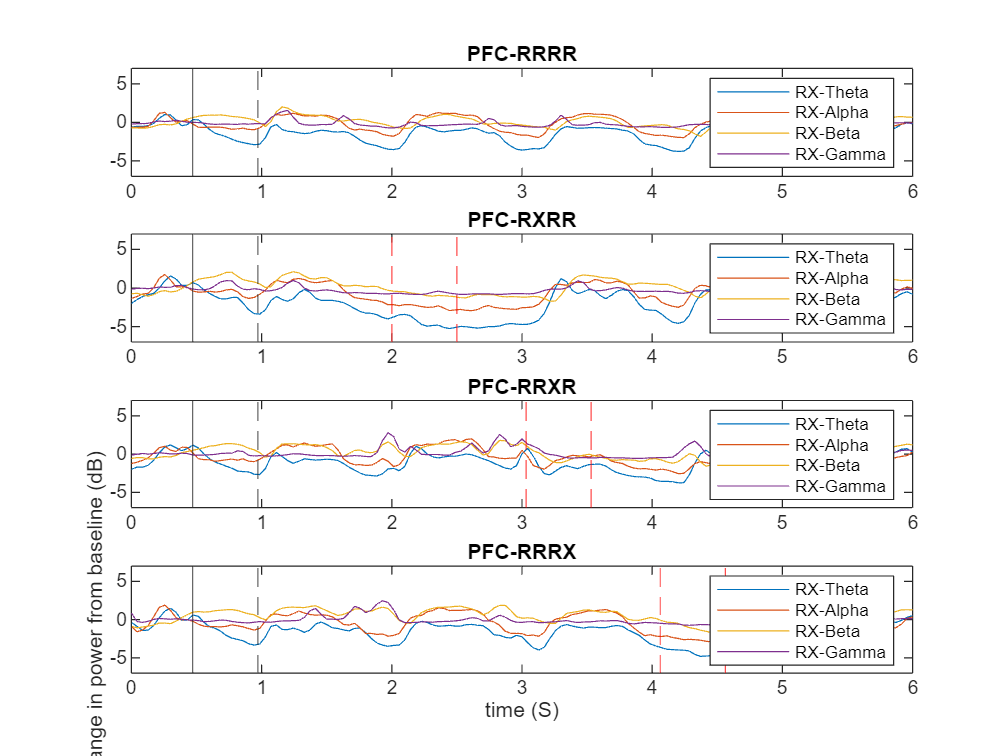

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(9, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(9, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(9, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(9, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("PFC-RRRR");
ylim([-7 7]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(10, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(10, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(10, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(10, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("PFC-RXRR");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(11, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(11, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(11, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(11, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("PFC-RRXR");ylim([-7 7]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(12, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(12, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(12, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(12, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("PFC-RRRX");ylim([-7 7]);
% xlim([0.4 6.0]);

fname = "PFC_TFRBandplot_3";
print(gcf,'-vector','-dsvg',fname +".svg");